# ACM 11 Homework 4 Part 1

You should read the problem set-up in this file and follow the instructions to write and test your code. This part is independent of Part 2, you can do them in any order. When you are done with both parts, zip all of your files needed to run the code into a single zip and upload to Canvas.

**Motivation**

It is of vital importance in the scientific or engineering practice to evaluate integrals like $\int_\Omega f(x)dx$, where $f$ is some function that doesn't necessarily have an analytical form but only supports evaluation, and the region $\Omega \subset {\mathbf{R}}^d$. Even if sometimes people are lucky enough to meet an analytical $f$, we could still have no access to a closed-form formula for the integral (for example, try evaluating $\int_{-\infty}^y e^{-x^2} dx$). 

The numerical solution to such integral $\int_\Omega f(x)dx$ consists of two approached: a deterministic one named numerical quadrature, and a stochastic one called the Monte Carlo method. 

To start with, we clean our Workspace in MATLAB to avoid confusion.

clear

### Problem 1: Numerical Quadrature

Numerical quadrature is a very classic method that estimates the integral $\int_\Omega f(x)dx$ by a weighted sum: $\int_\Omega f(x)dx \approx \sum_{=1,2,...,n}w_i f(x_i)$. The weights $w_i$ and the abscissa $x_i$ are carefully chosen so that the estimate is accurate for a large class of anonymous function $f$. ("Abscissa" is a fancy way to refer to the horizontal coordinate of a graph, and is common in quadrature literature.)

Define out target functions: $f\left(x\right)=e^{x-x^2 \;\sin \left(2x\right)}$ and $g\left(x,y\right)=e^{x^2 +y-\tanh \left(2y\right)}$.

Replace the 0 in the code block below with the appropriate function.

f = @(x) exp(x-x.^2.*sin(2*x));
g = @(x,y) exp(x.^2+y-tanh(2*y));

Let the region $\Omega ={\left\lbrack 0,1\right\rbrack }^d$. For dimension $d=1,2$, complete the skeleton code for the Gaussian quadrature rule `GQ`. Here $n$ is the number of abscissas we would have along one dimension. In other words, there are $n^d$ abscissas in total. See the notes/class slides on multivariate integrals for the appropriate formula for approximating a 2D integral.

For $n=2,3,4,5,6,7,8$, compare the output of the `GQ` function with the output of the built-in functions `integral` and `integral2` (for $d=1,2$respectively). You should measure the error of `GQ` with respect to the reference integral value by absolute value, and plot it against the number of total abscissas used (be careful, it should be $n^d$). Put the error plot for $f$ and $g$ in one single figure, mark their data points with different styles and colors, and use the log scale for $x$- and $y$-axes. Include appropriate axes labels and a legend. You may find the function `loglog `helpful.

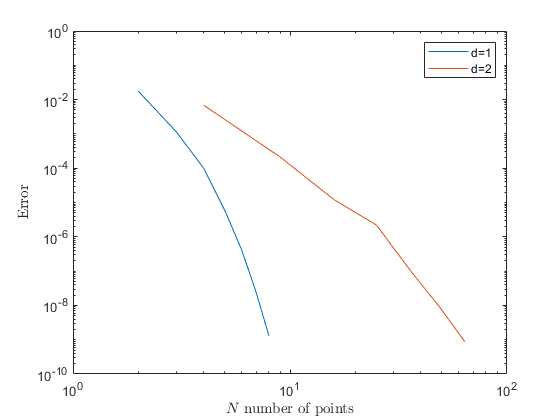

ref1 = integral(f,0,1);
ref2 = integral2(g,0,1,0,1);
n = 2:8;
err = zeros(length(n),2);
for i=1:length(n)
    e1 = abs(GQ(f,1,n(i))-ref1);
    e2 = abs(GQ(g,2,n(i))-ref2);
    err(i,:) = [e1 e2];
end
figure(1);clf;
loglog(n,err(:,1)); hold on 
loglog(n.^2,err(:,2));
xlabel('$N$ number of points','interpreter','latex'); 
ylabel('Error','interpreter','latex'); 
legend('d=1','d=2'); 

How does the convergence of the quadrature estimate the integral (slope of the error) differ between these two functions? Explain your observation in terms of the integral dimension $d$.

**The quadrature estimate of the integral converges faster for the lower dimension f than it does for the higher dimension g.**

### Problem 2: Monte Carlo Estimate

Another approach to estimate the integral $\int_\Omega f(x)dx$ is to write it as in the expectation form: $\int_\Omega f(x)dx = |\Omega| {\bf E}_{u\sim U(\Omega)}[f(u)]$, here $|\Omega |$ is the length/area/volume of the region $\Omega$, and $u$ is a random variable that is uniformly distributed on $\Omega$. Then, we can use the Monte Carlo method to estimate this expectation. Let $u_1 ,\ldotp \ldotp \ldotp ,u_n$ be the i.i.d. samples from the uniform distribution on $\Omega$, then ${\bf E}_{u\sim U(\Omega)}[f(u)]\approx \frac{1}{n} \sum_{i=1,2,...,n}f(u_i)$. Thus we conclude that $\int_\Omega f(x) dx \approx \frac{|\Omega|}{n}\sum_{i=1,2,...,n}f(u_i)$. 

Write a function named `MCE` that takes in the function $f$, dimension $d$, and number of samples $n$, and outputs the Monte Carlo estimate. Here we assume that $\Omega ={\left\lbrack 0,1\right\rbrack }^d$. You may use `rand` to generate a random variable uniformly distributed between 0 and 1.

**Complete the **`MCE`** function at the bottom of this file with the appropriate function.**

For $n=10,100,1000,10000$, compare the output of the `MCE` function with the built-in functions `integral` and `integral2` (for $d=1,2$ respectively). Due to the randomness, for each $n$, we want you to call `MCE` for $100$ times, and use the mean of their absolute difference with respect to the reference integral value as the error. You may find the function `mean` helpful. Plot the error against the number of total samples used. Put the error plot for $f$ and $g$ in one single figure, mark their data points with different styles and colors, and use the log scale for both $x$- and $y$-axes. You may find the function `loglog `helpful.

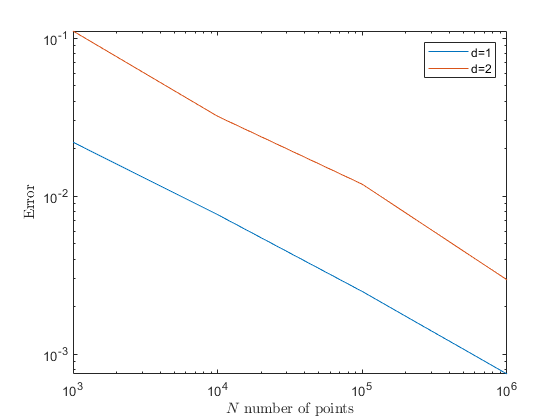

ref1 = integral(f,0,1);
ref2 = integral2(g,0,1,0,1);
n = [10,100,1000,10000];
err = zeros(length(n),2);
for i=1:length(n)
    s1 = 0;
    s2 = 0;
    for j=1:100
        s1 = s1 + abs(MCE(f,1,n(i))-ref1);
        s2 = s2 + abs(MCE(g,2,n(i))-ref2);
    end
    e1 = s1/100;
    e2 = s2/100;
    err(i,:) = [e1 e2];
end
figure(2);clf;
loglog(n*100,err(:,1)); hold on 
loglog(n*100,err(:,2));
xlabel('$N$ number of points','interpreter','latex'); 
ylabel('Error','interpreter','latex'); 
legend('d=1','d=2'); 

How does the convergence of the Monte Carlo estimate of the integral (slope of the error) behave for these two functions? How is this different from the convergence behavior of the traditional quadrature approach? Is this theoretically expected?

**The convergence of the Monte Carlo estimate is approximately the same unlike that of the traditional quadrature approach. We expect this since the rate shouldn't depend on dimension.**

function I = MCE(func,d,n)
assert(d==1|d==2,"Invalid dimension")
x = rand([d n]);
if d==1
    f = func(x);
else
    f = func(x(1,:),x(2,:));
end
I = sum(f)/n;
end

Please report the number of hours you spent on this part of the homework: 2 hours